syms a b c d e f g h i j k l T T0 lambda u(T,lambda)

a = 0.1445

a = 0.1445

b = 1356.8

b = 1.3568e+03

c = 489.6

c = 489.6000

d = 46.4

d = 46.4000

e = 0.93

e = 0.9300

f = 7.768

f = 7.7680

g = 3.36

g = 3.3600

h = 0.8

h = 0.8000

i = 0.0975

i = 0.0975

j = 0.0485

j = 0.0485

k = 0.75

k = 0.7500


%lambda = 1

T0=273.15

T0 = 273.1500

R = 287

R = 287


u(T,lambda) = a*(b+((c+(d/(power(lambda,e))))*(T-T0)*(10^-2))+((f+(g/(power(lambda,h))))*((T-T0)^2)*(10^-4))-((i+(j/(power(lambda,k))))*((T-T0)^3)*(10^-6)))

$$u(T, lambda) = \frac{289\,\left(\frac{232}{5\,\lambda^{93/100}}+\frac{2448}{5}\right)\,\left(T-\frac{5463}{20}\right)}{200000}+\frac{289\,\left(\frac{84}{25\,\lambda^{4/5}}+\frac{971}{125}\right)\,{\left(T-\frac{5463}{20}\right)}^{2}}{20000000}-\frac{289\,\left(\frac{97}{2000\,\lambda^{3/4}}+\frac{39}{400}\right)\,{\left(T-\frac{5463}{20}\right)}^{3}}{2000000000}+\frac{122536}{625}$$

%var2 = vpa(u)



du_dt = diff(u,T)

$$du\_dt(T, lambda) = \frac{8381}{125000\,\lambda^{93/100}}+\frac{289\,\left(2\,T-\frac{5463}{10}\right)\,\left(\frac{84}{25\,\lambda^{4/5}}+\frac{971}{125}\right)}{20000000}-\frac{867\,\left(\frac{97}{2000\,\lambda^{3/4}}+\frac{39}{400}\right)\,{\left(T-\frac{5463}{20}\right)}^{2}}{2000000000}+\frac{44217}{62500}$$

var = vpa(du_dt)

$$var(T, lambda) = 0.00001445\,\left(\frac{3.36}{\lambda^{4/5}}+7.768\right)\,\left(2.0\,T-546.3\right)-0.0000004335\,\left(\frac{0.0485}{\lambda^{3/4}}+0.0975\right)\,{\left(T-273.15\right)}^{2}+\frac{0.067048}{\lambda^{93/100}}+0.707472$$

%var3 = vpa(du_dt)

du_dlambda = diff(u,lambda);
%var = vpa(ans)

du_dt(300,1)

$$ans = \frac{313243724245621}{400000000000000}$$

var2 = vpa(ans)

$$var2 = 0.7831093106140525$$

du_dt(3000,1)

$$ans = \frac{472343679409621}{400000000000000}$$

var3 = vpa(ans)

$$var3 = 1.1808591985240525$$

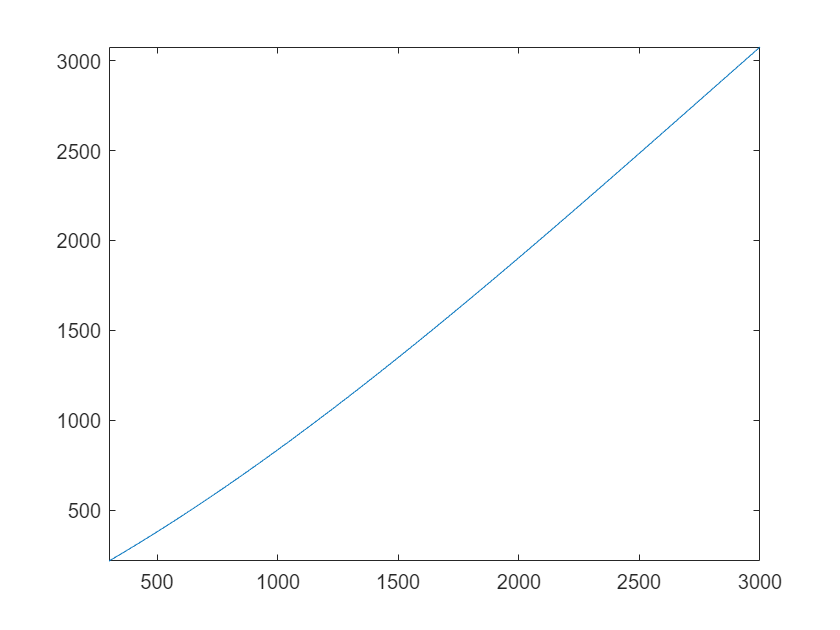


c_p = du_dt+R/1000;
kappa = c_p/du_dt;

fplot(@(T) u(T,1),[300 3000])

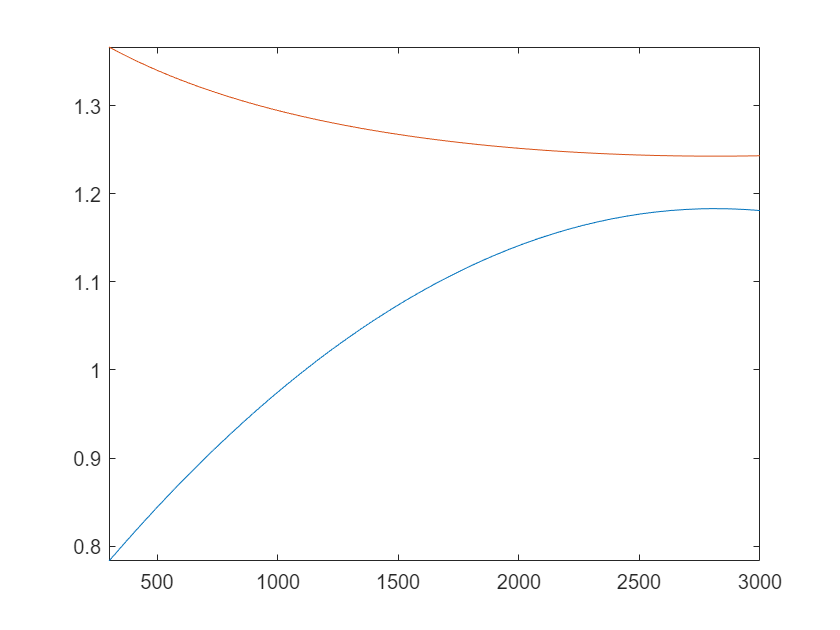

fplot(du_dt(T,1),[300 3000]);
hold on
fplot(kappa(T,1),[300 3000])
hold off